# SESSIÓ 9: DESCRIPTORS

### CARLES TORNEL BONFILL

### LORENZO SABATER FANDOS

## 1. Processat + Segmentació + Etiquetat + Descripció de regions

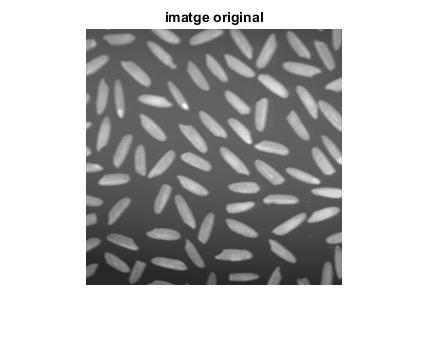

clear,close all
orig = imread ('arros.tif');
imshow(orig), title('imatge original')

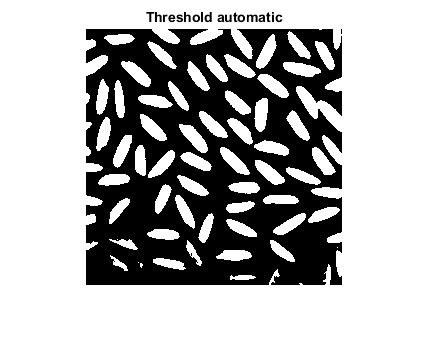


% segmentem per binarització
bw=im2bw(orig, graythresh(orig)); % Binarització per Otsu
figure, imshow(bw),title('Threshold automatic')

#### No funciona, perdem grans. No confieu mai en els detectors automatics de llindar.

#### El problema està en que la iluminació no és gens homogènea.

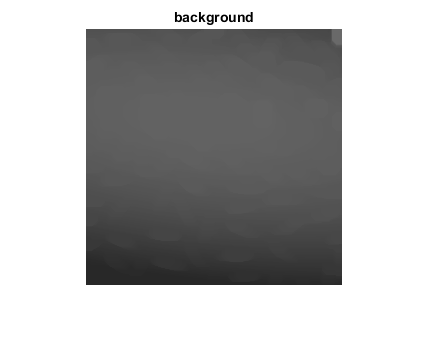

% Fem un filtratge morfològic
bg = imopen(orig,strel('disk',10));
figure, imshow(bg),title('background')

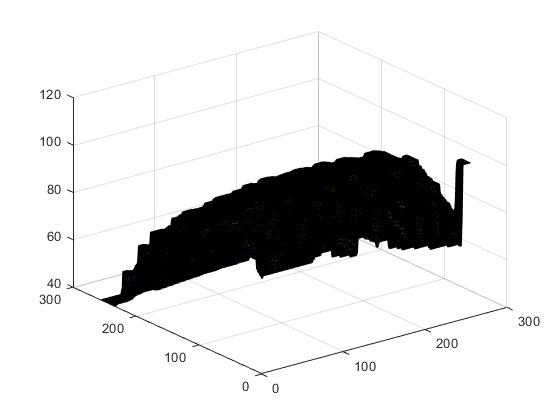

figure, surf(bg) % mostrem el background com si fos una superfície

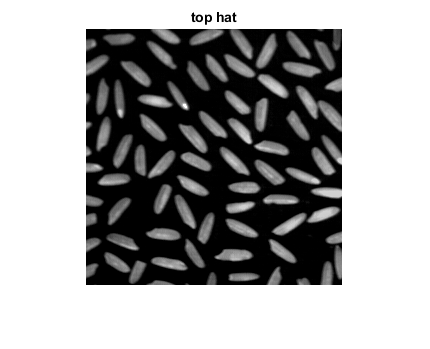


%Li restem el background a la imatge
y = imsubtract(orig,bg);
figure, imshow(y, []), title( 'top hat')

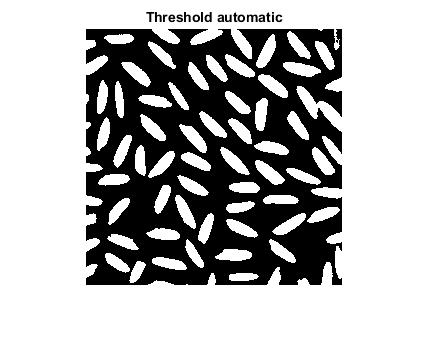


% tornem a segmentar per Otsu
bw=im2bw(y, graythresh(y));
figure, imshow(bw),title('Threshold automatic')

#### Ara si!

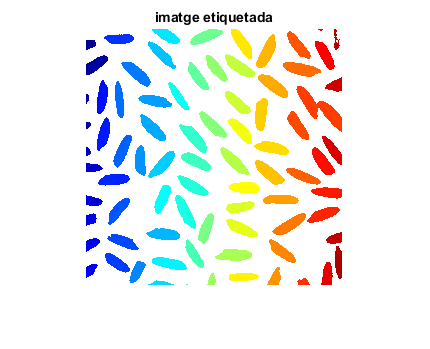

% etiquetem la imatge segmentada
[eti num] = bwlabel(bw,4);
figure,imshow(label2rgb(eti)), title('imatge etiquetada')


% Comptem ara el nombre d’objectes a la imatge
num

num = 81

%o be:
max(eti(:))

ans = 81


% obtenim descriptors de les regions
Dades=regionprops(eti,'all');

#### Comproveu en el workspace la variable Dades. Quines propietats hem extret de cada regió?

#### Consulteu el help de la funció regionprops.

% Podem obtenir una dada de l’objecte 50 de la forma:
Dades(50).Area

ans = 305

% O be un vector amb totes les Àrees:
Arees=[Dades.Area];


### Exercici: en la imatge segmentada, separeu els grans d’arròs que es toquen. Desprès elimineu els grans d’arròs que toquen les vores. Tots aquests grans falsejaven el resultat. Amb la nova imatge etiquetatda, obteniu les propietats que us semblin adients usant regionprops.

### Representeu mitjançant plots o diagrames de barres aquelles propietats que us semblin interessants per a fer un control de qualitat dels grans d’arròs. 

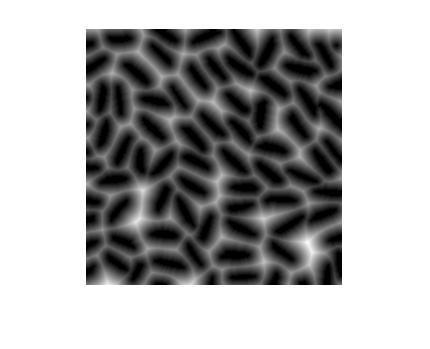

im = bw;

ee = strel('disk',3);
ero = imerode(im,ee);

%Separem grans d'arròs que es toquen
D = bwdist(ero, 'euclidean');
imshow(D,[])

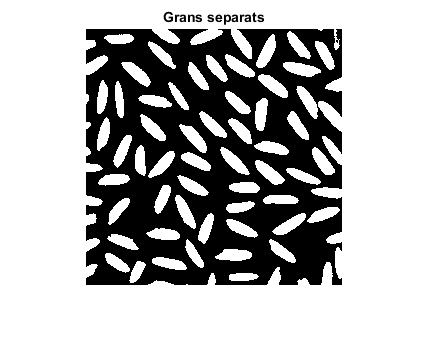

DL = watershed(D);
bgm = DL == 0;
sep = imsubtract(im,bgm);
imshow(sep)
title('Grans separats')

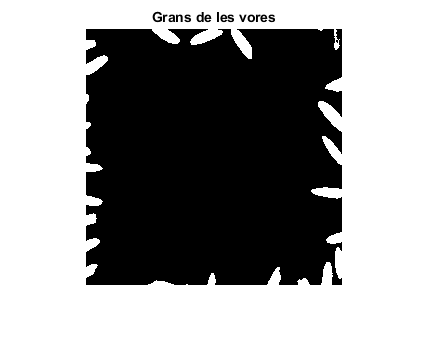


%Eliminem grans d'arròs que toquen les vores
mark = ones(256);
mark(2:end-1, 2:end-1) = 0;

rec = imreconstruct(mark, sep);
imshow(rec); title('Grans de les vores')

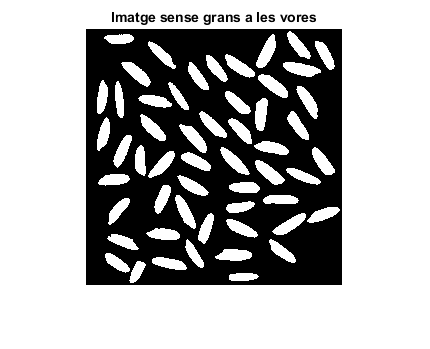

res = sep - rec;
imshow(res); title('Imatge sense grans a les vores')

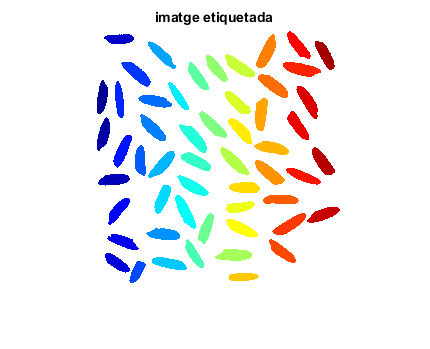


% etiquetem la imatge segmentada
[eti, num] = bwlabel(res,4);
figure,imshow(label2rgb(eti)), title('imatge etiquetada')


% Comptem ara el nombre d’objectes a la imatge
num

num = 54

%o be:
max(eti(:))

ans = 54

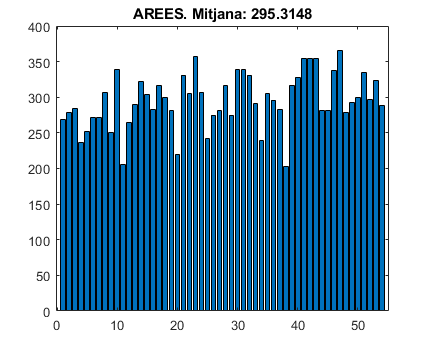


% obtenim descriptors de les regions
Dades=regionprops(eti,'all');


%GRÀFICS DE DESCRIPTORS

%Area de cada grà d'arròs
Arees=[Dades.Area];
mitjana = mean(Arees);
bar(Arees); title(['AREES. Mitjana: ',num2str(mitjana)])

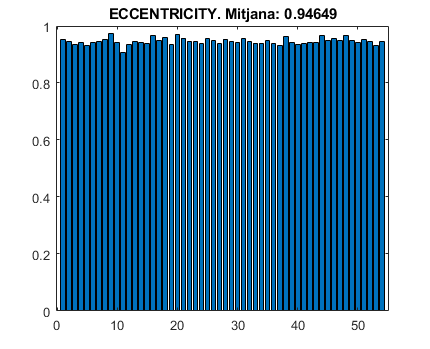


%Relació de distància entre el centre de cada grà d'arròs i els seus eixos
Eccentricity=[Dades.Eccentricity];
mitjana = mean(Eccentricity);
bar(Eccentricity); title(['ECCENTRICITY. Mitjana: ',num2str(mitjana)])

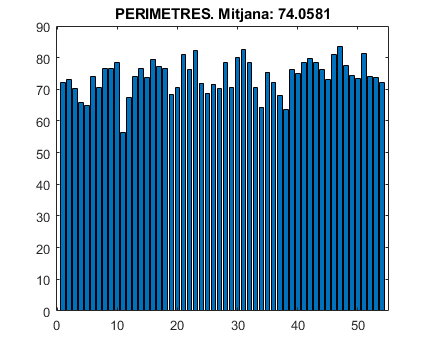


%Com que el perímetre generalment va lligat a l'àrea, podem trobar un descriptor
%característic als grans d'arròs
Perimetres=[Dades.Perimeter];
mitjana = mean(Perimetres);
bar(Perimetres); title(['PERIMETRES. Mitjana: ',num2str(mitjana)])

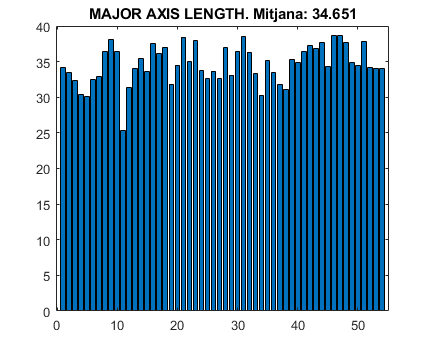


%Descriptor de tamany de cada grà d'arròs
MajorAxisLength=[Dades.MajorAxisLength];
mitjana = mean(MajorAxisLength);
bar(MajorAxisLength); title(['MAJOR AXIS LENGTH. Mitjana: ',num2str(mitjana)])

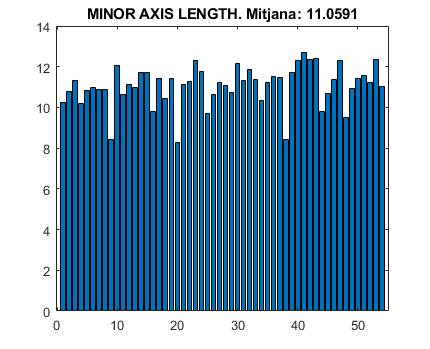


%Descriptor de tamany de cada grà d'arròs
MinorAxisLength=[Dades.MinorAxisLength];
mitjana = mean(MinorAxisLength);
bar(MinorAxisLength); title(['MINOR AXIS LENGTH. Mitjana: ',num2str(mitjana)])

## 2. Codis de cadena

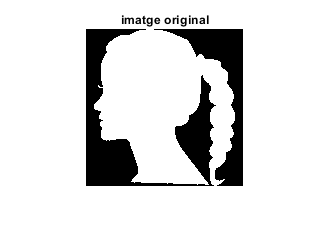

clear all, close all
im=imread('head.png');
% no cal tan gran
im=imresize(im,1/4);
imshow(im), title('imatge original')

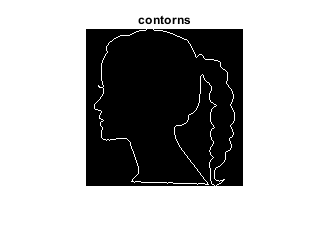


% obtenim el contorn
ero=imerode(im,strel('disk',1));
cont=xor(ero,im);
figure,imshow(cont), title('contorns')

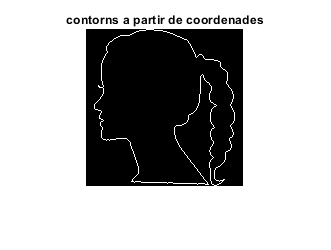


% obtenim les coordenades del contorn
[fila col] = find(im,1); % Busquem el primer píxel
B = bwtraceboundary(im,[fila col],'E'); %direccio est a l'atzar
% B conté les coordenades

% Ho comprovem mostrant el resultat
aux=zeros(size(im));
aux(sub2ind(size(aux),B(:,1),B(:,2)))=1;
figure,imshow(aux),title ('contorns a partir de coordenades')

### Exercici: trobar els codis de cadena incrementals a partir de B

%Assignem un numero a cada direcció
W = [-1,0]; %1
NW = [-1,-1]; %2
N = [0,1]; %0
NE = [1,1]; %4
E = [1,0]; %3
SE = [1,-1]; %6
S = [0,-1]; %5
SW = [-1,-1]; %8

%Inicialitzem la cadena a 0. Lllargada de la cadena = mida de B-1
llargada = length(B)-1

llargada = 754

cadena = zeros(1,llargada);
%Casella inicial = Primer element de B
old = B(1,:);

%Per cada element de B començant des del segon fins al final,
%calculem la coordenada del nou pixel, i depenent del seu valor li assignem
%a codi el nombre associat corresponent a la coordenada cercada.
%Actualitzem la variable old al següent element
for j = 2:length(B)
    
    coord = B(j,:) - old;
    old = B(j,:);
    
    if (coord == W) %WEST
        cadena(:,j-1) = 1;
    
elseif (coord == NW) %NORTH WEST
        cadena(:,j-1) = 2;
    
elseif (coord == N) %NORTH
        cadena(:,j-1) = 0;
    
elseif (coord == NE) %NORTH EAST
        cadena(:,j-1) = 4;
    
elseif (coord == E) %EAST
        cadena(:,j-1) = 3;
    
elseif (coord == SE) %SOUTH EAST
        cadena(:,j-1) = 6;
    
elseif (coord == S) %SOUTH
        cadena(:,j-1) = 5;
    
elseif (coord == SW) %SOUTH WEST
        cadena(:,j-1) = 8;
    end
    
end

%Cadena estàndard
cadena

cadena =      0     0     0     0     0     0     1     0     0     1     0     1     1     1     1     1     2     5     5     5     2     1     4     4     0     0     0     1     2     1     1     1     2     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1



%Transformem a cadena incremental
cadena_final = incremental(cadena, 7);

%Cadena incremental
cadena_final

cadena_final =      0     0     0     0     0     1     7     0     1     7     1     0     0     0     0     1     3     0     0     5     7     3     0     4     0     0     1     1     7     0     0     1     7     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     7


## 3. Descriptors de Fourier

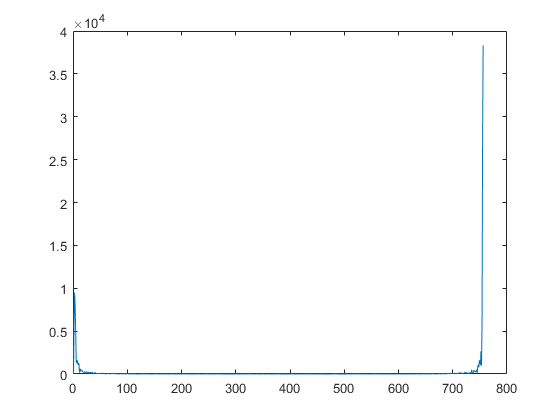

% centrem coordenades
mig=mean(B);
B(:,1)=B(:,1)-mig(1);
B(:,2)=B(:,2)-mig(2);

% Convertim les coordenades a complexes
s= B(:,1) + i*B(:,2);

% Cal que la dimensio del vector sigui parell
[mida bobo]=size(B);
if(mida/2~=round(mida/2))
s(end+1,:)=s(end,:); %dupliquem l'ultim
mida=mida+1;
end

% Calculem la Fast Fourier Transform
z=fft(s);
% representem l’espectre
figure,plot(abs(z))

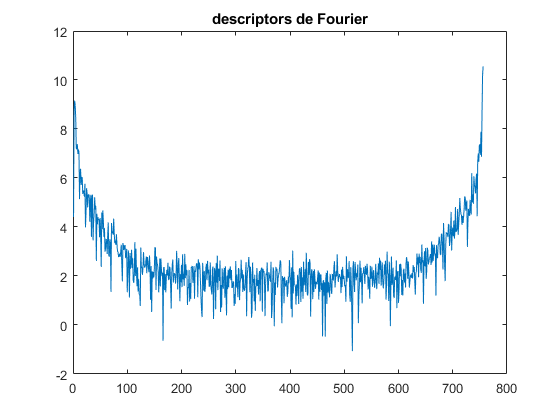

% ho displaiem logaritmic perque no es veu res
figure,plot(log(abs(z))), title ('descriptors de Fourier')

#### Observeu que l’espectre surt duplicat, amb un efecte mirall. És una propietat de la trasnformada de Fourier, que ara no ve al cas. 

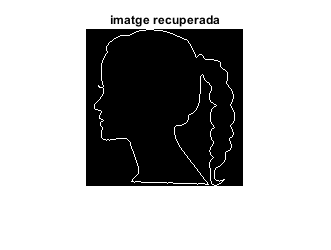

% Recuperem la imatge original per comprovar que el procés és reversible
ss=ifft(z); % Transformada de Fourier inversa
files= round(real(ss)+mig(1));
cols=round(imag(ss)+mig(2));
aux(:,:)=0;
aux(sub2ind(size(aux),files,cols))=1;
figure,imshow(aux), title('imatge recuperada')

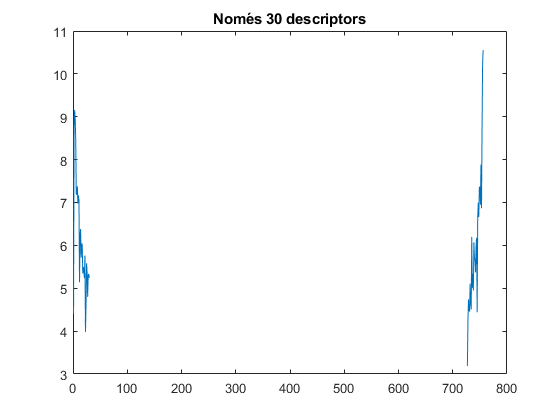


%% Reduim la quantitat de descriptors de Fourier
N=30; % agafem N descriptors
tmp=z;
tmp(N+1:end-N)=0; % eliminem els del mig perque es duplica l'espectre
figure, plot(log(abs(tmp))), title ('Només 30 descriptors')

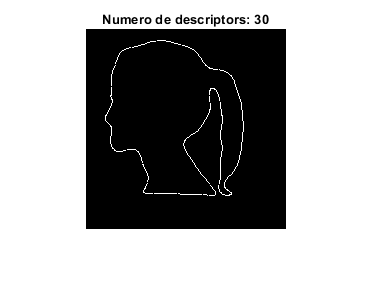


% Tornem al pla imatge a partir de l’espectre modificat
ss2=ifft(tmp);
% Les coordenades resultants poden sortir del rang de la imatge original
% Creo una imatge més gran per a que les coordenades no s'em surtin de mare
mida=200;
files= round(real(ss2)+mida/2);
cols=round(imag(ss2)+mida/2);
aux=logical(zeros(mida));
aux(sub2ind(size(aux),files,cols))=1;
figure,imshow(aux)
title(['Numero de descriptors: ',num2str(N)]);

### Exercici: Repetiu el procés utilitzant diferents quantitats de descriptors i expliqueu quin efecte té això en el detall de la imatge obtinguda

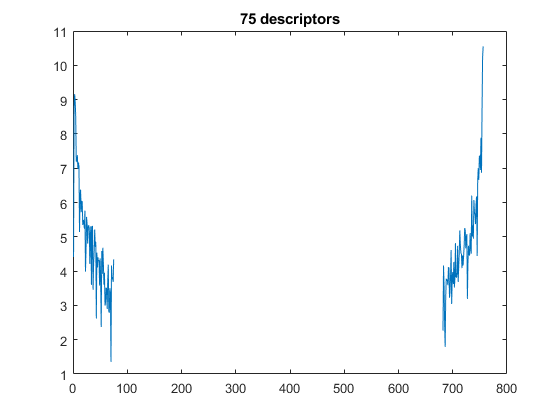

%% 75 DESCRIPTORS DE FOURIER
N= 75; % agafem N descriptors
tmp=z;
tmp(N+1:end-N)=0; % eliminem els del mig perque es duplica l'espectre
figure, plot(log(abs(tmp))), title ('75 descriptors')

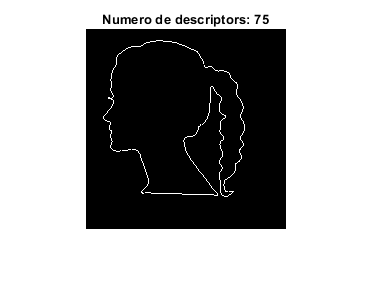


% Tornem al pla imatge a partir de l’espectre modificat
ss2=ifft(tmp);
% Les coordenades resultants poden sortir del rang de la imatge original
% Creo una imatge més gran per a que les coordenades no s'em surtin de mare
mida=200;
files= round(real(ss2)+mida/2);
cols=round(imag(ss2)+mida/2);
aux=logical(zeros(mida));
aux(sub2ind(size(aux),files,cols))=1;
figure,imshow(aux)
title(['Numero de descriptors: ',num2str(N)]);

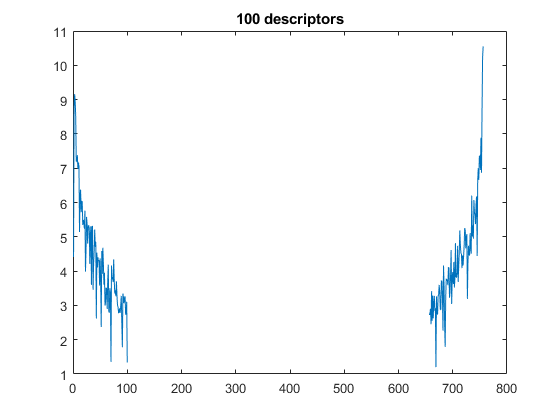




%% 100 DESCRIPTORS DE FOURIER
N=100; % agafem N descriptors
tmp=z;
tmp(N+1:end-N)=0; % eliminem els del mig perque es duplica l'espectre
figure, plot(log(abs(tmp))), title ('100 descriptors')

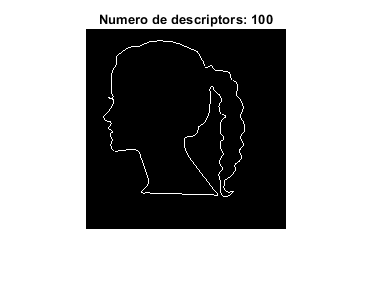


% Tornem al pla imatge a partir de l’espectre modificat
ss2=ifft(tmp);
% Les coordenades resultants poden sortir del rang de la imatge original
% Creo una imatge més gran per a que les coordenades no s'em surtin de mare
mida=200;
files= round(real(ss2)+mida/2);
cols=round(imag(ss2)+mida/2);
aux=logical(zeros(mida));
aux(sub2ind(size(aux),files,cols))=1;
figure,imshow(aux)
title(['Numero de descriptors: ',num2str(N)]);

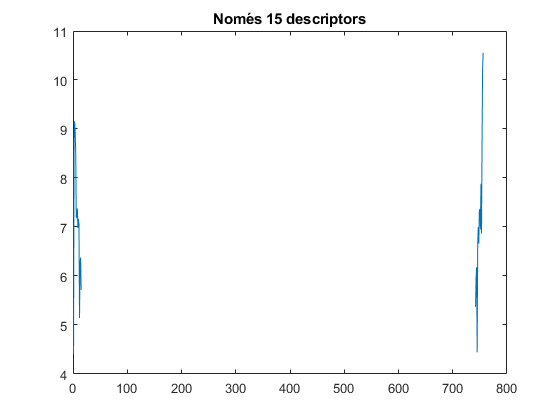



%% 15 DESCRIPTORS DE FOURIER
N=15; % agafem N descriptors
tmp=z;
tmp(N+1:end-N)=0; % eliminem els del mig perque es duplica l'espectre
figure, plot(log(abs(tmp))), title ('Només 15 descriptors')

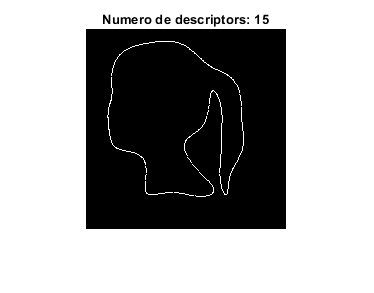


% Tornem al pla imatge a partir de l’espectre modificat
ss2=ifft(tmp);
% Les coordenades resultants poden sortir del rang de la imatge original
% Creo una imatge més gran per a que les coordenades no s'em surtin de mare
mida=200;
files= round(real(ss2)+mida/2);
cols=round(imag(ss2)+mida/2);
aux=logical(zeros(mida));
aux(sub2ind(size(aux),files,cols))=1;
figure,imshow(aux)
title(['Numero de descriptors: ',num2str(N)]);

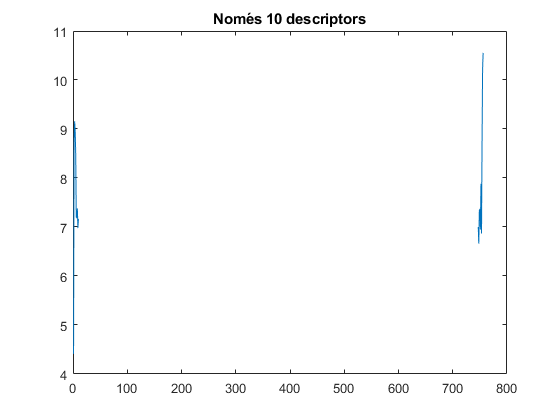




%% 10 DESCRIPTORS DE FOURIER
N=10; % agafem N descriptors
tmp=z;
tmp(N+1:end-N)=0; % eliminem els del mig perque es duplica l'espectre
figure, plot(log(abs(tmp))), title ('Només 10 descriptors')

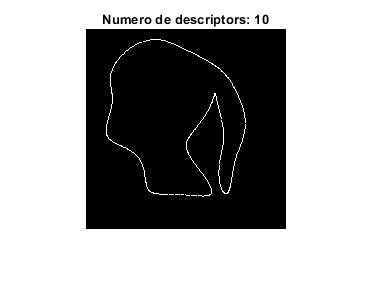


% Tornem al pla imatge a partir de l’espectre modificat
ss2=ifft(tmp);
% Les coordenades resultants poden sortir del rang de la imatge original
% Creo una imatge més gran per a que les coordenades no s'em surtin de mare
mida=200;
files= round(real(ss2)+mida/2);
cols=round(imag(ss2)+mida/2);
aux=logical(zeros(mida));
aux(sub2ind(size(aux),files,cols))=1;
figure,imshow(aux)
title(['Numero de descriptors: ',num2str(N)]);

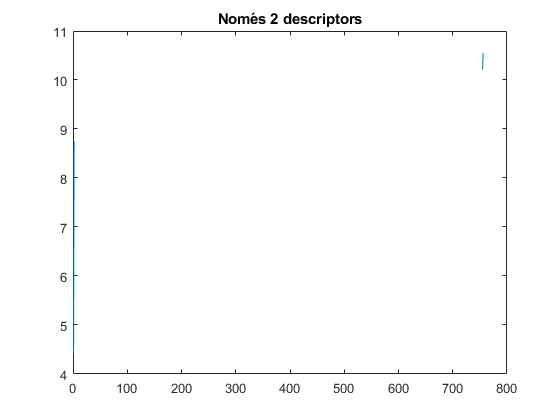




%% 2 DESCRIPTORS DE FOURIER
N=2; % agafem N descriptors
tmp=z;
tmp(N+1:end-N)=0; % eliminem els del mig perque es duplica l'espectre
figure, plot(log(abs(tmp))), title ('Només 2 descriptors')

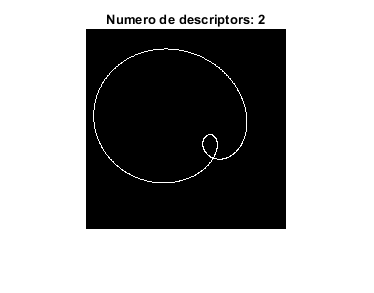


% Tornem al pla imatge a partir de l’espectre modificat
ss2=ifft(tmp);
% Les coordenades resultants poden sortir del rang de la imatge original
% Creo una imatge més gran per a que les coordenades no s'em surtin de mare
mida=200;
files= round(real(ss2)+mida/2);
cols=round(imag(ss2)+mida/2);
aux=logical(zeros(mida));
aux(sub2ind(size(aux),files,cols))=1;
figure,imshow(aux)
title(['Numero de descriptors: ',num2str(N)]);

#### Després de fer l'experiment en diferents números de descriptors, podem assegurar que quan més descriptors de Fourier es presenten, més és el nivell de detall que la imatge presenta.

#### Un cop es sobrepassa un cert límit, el nivell de detall ja no pot augmentar més ja que hem assolit el màxim possible. Per l'altra banda, el mínim és 1 descriptor de Fourier, que mostra només una freqüència i es representa en forma de circumferència.

#### Això és degut al tipus de freqüència: més descriptors de Fourier presentaràn més freqüència a l'experiment i per conseqüència més nivell de detall. Menys descriptors de Fourier senyalen menys freqüència i per tant mostraran una imatge amb molt poc detall.

function y = incremental(cadena, max_value)
    max_value = max_value+1;
    [f co] = size(cadena);
    inc = zeros(1,co);
    
    for i = (1: co-1)
        if(cadena(1,i) > cadena(1,i+1))
            inc(1,i) = max_value - abs(cadena(1,i)-cadena(1,i+1));
        else
            inc(1,i) = abs(cadena(1,i)-cadena(1,i+1));
        end
    end
    
    if(cadena(1,end) > cadena(1,1))
            inc(1,end) = max_value - abs(cadena(1,end)-cadena(1,1));
    else
            inc(1,end) = abs(cadena(1,end)-cadena(1,1));
    end
    
    y = inc;

end